# Lab Session 2

**Multibody System Dynamics**

A simulation reproduces de behaviour of a model over time given some initial conditions. This lab session deals with:

- **Equations of motion**

- **Time inegrators**

## Equations of Motion

The equations of motion of a multibody system for the set of $n$ independent coordinates ${\bf q}$ can be written in matrix form as follows:


$${\bf M} \ddot{\bf q} + {\bf c} = {\bf f}$$


where ${\bf M}({\bf q})$ is the $n \times n$ mass matrix, ${\bf c} ({\bf q}, \dot{\bf q})$ is the vector of Coriolis and centrifugal terms, and ${\bf f}$ is the vector of generalized forces.

## Euler's Time-Integrator

Given a function $x(t)$ and a differential equation $\dot{x} = f(x, t)$, a solution to an initial value problem from $x(t_0) = x_0$ can be expressed resursively using Euler's method as


$$x(t+h) = x(t) + h f(x(t),t)$$


Where $h$ is the time-step size.

In mechanics, an initial value problem can be formulated for the coordinates ${\bf q}(t_0) = {\bf q}_0$ and velocities $\dot{\bf q}(t_0) = \dot{\bf q}_0$. The acceleration $\ddot{\bf q}(t)$ can be found from the equations of motion, which allows us to update of velocity $\dot{\bf q}$ and coordinates ${\bf q}$ using Euler's method as


$$\dot{\bf q}(t + h) = \dot{\bf q}(t) + h \ddot{\bf q}$$



$${\bf q}(t + h) = {\bf q}(t) + h \dot{\bf q}$$


# Assignment

## Double Pendulum

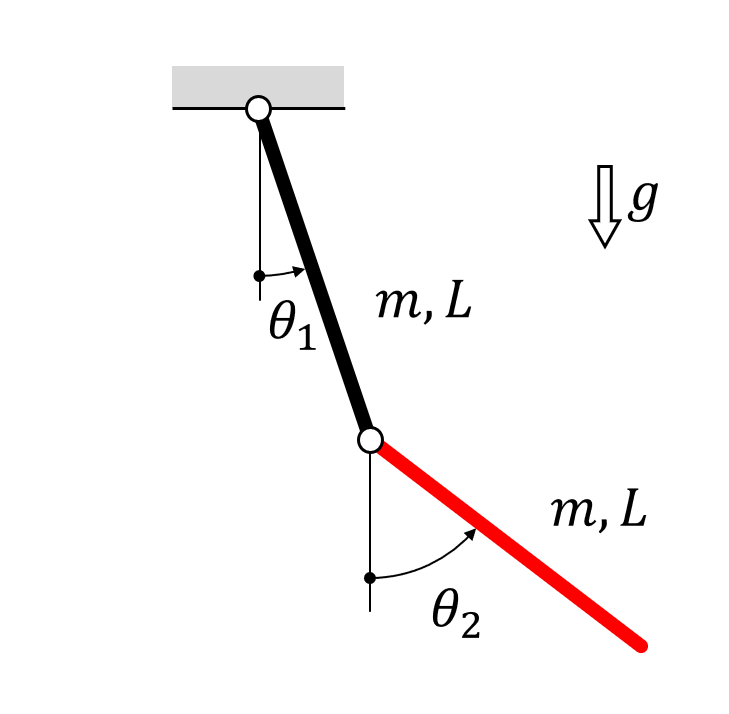

These are the equations of motion of a double pendulum. The angle $\theta_1$ and $\theta_2$ define the orientation of the links with respect to the vertical direction, and the equilibrium position $\theta_1 = \theta_2 = 0$.


$$\left[\matrix{\frac{m_1}{3} L_1^2 + m_2 L_1^2 
& \frac{m_2}{2} L_1 L_2 \cos(\theta_1-\theta_2) 
\cr \frac{m_2}{2} L_1 L_2 \cos(\theta_1-\theta_2)  
& \frac{m_2}{3} L_2^2}\right]
\left[ \matrix{ \ddot{\theta}_1 \cr \ddot{\theta}_2 } \right]
+
\left[ \matrix{ \frac{m_2}{2} L_1 L_2 \dot{\theta}_2^2 \sin (\theta_1 - \theta_2) 
\cr - \frac{m_2}{2} L_1 L_2 \dot{\theta}_1^2 \sin (\theta_1 - \theta_2)  } \right]
=
\left[ \matrix{ - \left( \frac{m_1}{2} + m_2 \right) g L_1 \sin \theta_1
\cr - \frac{m_2}{2} g L_2 \sin \theta_2  } \right]$$


### 1. Simulation

Write a program to simulate the double pendulum starting from an initial orientation of the links. Use these lines as starting point

% Model parameters
m1 = 1;
m2 = 1;
L1 = 1;
L2 = 1;

% Initialize Model and Viewer
model = DoublePendulum([m1, m2], [L1, L2]);
viewer = model.initViewer([-2, 2], [-2, 1]);
system = System(model);

% Initialize variables
% ...

steps = 100;
for k = 1 : steps
    
    % Update System before calculations
    system.update();
    
    % Solve equations of motion
    % M = [];
    % c = [];
    % f = [];
    % ...
    
    % Update Model and Viewer after
    model.update();
    viewer.update();
end

### 2. Mechanical Energy

Implement the **kinetic energy** and **potential energy **of the doble pendulum, and analyze the total** mechanical energy** in terms of the time-step size.

% T = ...
% U = ...
% E = T + U;

### **Questions**

- Run a 10 second simulation staring from $\theta_1 = \theta_2 = \frac{\pi}{2}$ and $\dot\theta_1 = \dot\theta_2 = 0$ using different time step sizes ($h = 0.1\,{\rm s}, 0.01\,{\rm s}, 0.001\,{\rm s} \dots $). How does the time-step size affect the total mechanical energy of the system?

- The time-integration of the generalized coordinates and velocities can be done in two ways: first coordinates, then velocities, or first velocities, then coordinates. How does the order of integration affect the mechanical energy of the system?